# HAND-EYE CALIBRATION

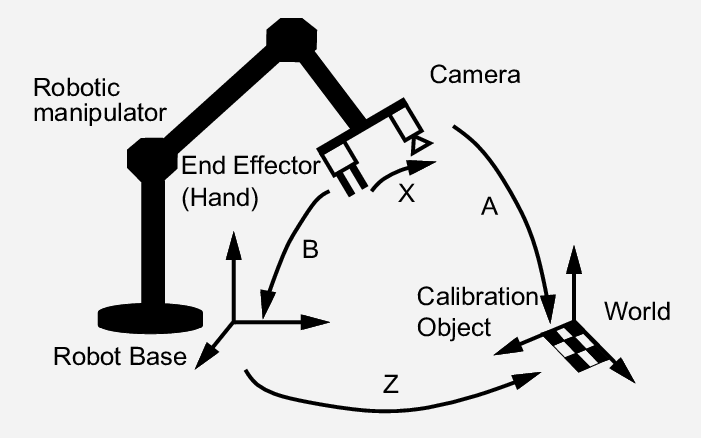

## 1- Parameters

n = 16; % Number of camera poses
n_matrix = reshape(1:n, [], 1);
combinations = nchoosek(n_matrix, 2);

load('CameraParams.mat');
load('Poses/Hand_eye_poses.mat');

## 2-  Data

bTgi=get_T_pose(AEul, BEul, CEul,X,Y,Z);
cTpi=get_T_cam(cameraParams);

## 3- Estimate g_Tc using simple quaternions

C=[];
for j = 1:length(combinations)

    TA = pinv(bTgi(:,:,combinations(j,1)))*bTgi(:,:,combinations(j,2));
    TB = cTpi(:,:,combinations(j,1))*pinv(cTpi(:,:,combinations(j,2)));

#### Quaternion Solution of the Equation RA RX = RX RB

    % Extract rotation part of the matrices
    RA = TA(1:3, 1:3);
    RB = TB(1:3, 1:3);
    
    % Compute the quaternion representation of the rotations
    qa = rotm2quat(RA);
    qb = rotm2quat(RB);
    
    % Ensure the scalar parts of qa and qb have the same sign
    if sign(qa(1)) ~= sign(qb(1))
        qb = -qb;
    end
    
    % Check if the real parts of qa and qb are close to zero
    threshold = 1e-5; % Adjust as needed
    if abs(qa(1)) < threshold || abs(qb(1)) < threshold
        disp("Warning: Real parts of qa or qb are close to zero. Discarding solution.");
        continue; % Discard the solution
    end
    
    % Compute quaternion equation coefficients
    qr_ra = qa(1);
    qr_rb = qb(1);
    vec_ra = qa(2:4);
    vec_rb = qb(2:4);
    vec_sum = vec_ra + vec_rb;
    vec_diff = vec_ra - vec_rb;
    dMatrix = [0, -vec_diff; vec_diff', vect2skew(vec_sum)];
    
    % Formulate the matrix C
    Ci = ((qr_ra - qr_rb) * eye(4)) + dMatrix;
    C = vertcat(C, Ci);
end

% Solve linear equation C * qx' = 0 using SVD
[~, ~, V] = svd(C);
qx = quatnormalize(V(:, end)');

% Ensure the real part is positive
if qx(1) < 0
    qx = -qx;
end

% Extract the rotation matrix RX from qx
RX = quat2rotm(qx);

% Display the estimated rotation matrix RX
disp("Estimated rotation RX:");

Estimated rotation RX:


disp(RX);

   -0.6905   -0.2223    0.6883
    0.7233   -0.2083    0.6583
   -0.0030    0.9525    0.3046



#### Calculation of the Translation Part

u=[];
b=[];
for j = 1:length(combinations)

    TA = pinv(bTgi(:,:,combinations(j,1)))*bTgi(:,:,combinations(j,2));
    TB = cTpi(:,:,combinations(j,1))*pinv(cTpi(:,:,combinations(j,2)));

    % Extract rotation part of the matrices
    RA = TA(1:3, 1:3);
    RB = TB(1:3, 1:3);

    % Extract translation part of the matrices
    PA = TA(1:3, 4);
    PB = TB(1:3, 4);
    
    % Compute the quaternion representation of the rotations
    qa = rotm2quat(RA);
    qb = rotm2quat(RB);
    
    % Ensure the scalar parts of qa and qb have the same sign
    if sign(qa(1)) ~= sign(qb(1))
        qb = -qb;
    end
    
    % Check if the real parts of qa and qb are close to zero
    threshold = 1e-5;
    if abs(qa(1)) < threshold || abs(qb(1)) < threshold
        disp("Warning: Real parts of qa or qb are close to zero. Discarding solution.");
        continue; % Discard the solution
    end

    % Calculate RA - I3x3
    RA_minus_I = RA - eye(3);
    
    u = [u;RA_minus_I];
    b = [b;RX * PB - PA];
end
    
    % Solve for PX
    PX = pinv(u) * b;
    disp("Estimated translation PX:");

Estimated translation PX:


    disp(PX);

   39.5475
   39.7776
  238.1988



#### SOLUTION TX = estimated g_Tc

estimated_g_Tc_simple = eye(4);
estimated_g_Tc_simple(1:3, 1:3) = RX;
estimated_g_Tc_simple(1:3, 4) = PX;
disp("Estimated Simple Quaternion TX:");

Estimated Simple Quaternion TX:


disp(estimated_g_Tc_simple);

   -0.6905   -0.2223    0.6883   39.5475
    0.7233   -0.2083    0.6583   39.7776
   -0.0030    0.9525    0.3046  238.1988
         0         0         0    1.0000



## 4- Estimate g_Tc using dual quaternions

C=[];
for j = 1:length(combinations)

    TA = pinv(bTgi(:,:,combinations(j,1)))*bTgi(:,:,combinations(j,2));
    TB = cTpi(:,:,combinations(j,1))*pinv(cTpi(:,:,combinations(j,2)));
    
    %Convert to dual quaternion
    qTA = tform2dq(TA);
    qTB = tform2dq(TB);

    qn_TA = qTA(1:4);
    qd_TA = qTA(5:8);
    qn_TB = qTB(1:4);
    qd_TB = qTB(5:8);

    % Ensure the same sign
    if sign(qn_TA(1)) ~= sign(qn_TB(1))
        qTB = -qTB;
    end

    % Check if COS close to zero
    threshold = 1e-5;
    if abs(qn_TA(1)) < threshold || abs(qn_TB(1)) < threshold
        disp("Warning: COS(Theta/2) are close to zero. Discarding solution.");
        continue; % Discard the solution
    end

    %Vectors
    v_qn_TA = qTA(2:4);
    v_qd_TA = qTA(6:8);
    v_qn_TB = qTB(2:4);
    v_qd_TB = qTB(6:8);

    Ci = [(v_qn_TA - v_qn_TB)' vect2skew(v_qn_TA + v_qn_TB) zeros(3,1) zeros(3,3);
          (v_qd_TA - v_qd_TB)' vect2skew(v_qd_TA + v_qd_TB) (v_qn_TA - v_qn_TB)' vect2skew(v_qn_TA + v_qn_TB)];
    C = vertcat(C, Ci);
end

% Solve linear equation C * qx' = 0 using SVD
[~, ~, V] = svd(C);

eig1 = V(:, end);
eig2 = V(:, end-1);

% Extract Vectors
u1 = eig1(1:4);
v1 = eig1(5:8);
u2 = eig2(1:4);
v2 = eig2(5:8);

%EQU 1
% Solve the quadratic equation
solutions = roots([(u1' * v1), (u1' * v2 + u2' * v1), (u2' * v2)]);
% Extract the real solutions
real_solutions = solutions(imag(solutions) == 0);

% Initialize maximum value and index
max_value = -Inf;
% Evaluate the equation for each real solution and find the maximum
for i = 1:length(real_solutions)
    s = real_solutions(i);
    equation_value = s^2 * (u1')*u1 + 2 * s * (u1')*u2 + (u2')*u2;
    if equation_value > max_value
        max_s = real_solutions(i);
    end
end

equation_value = 1.2556e-09

equation_value = 6.6736e-05


% Display the corresponding root
disp(['Maximize root: ', num2str(max_s)]);

Maximize root: 0.032397



%EQU 2
gamma2 = sqrt(1 /(max_s^2 * (u1')*u1 + 2 * max_s * (u1')*u2 + (u2')*u2));
gamma1 = gamma2 * max_s;

q_TX = gamma1 * eig1 + gamma2 * eig2;

% Normalize q_TX
q_TX_normalized = dqunit(q_TX');

% Convert q_TX_normalized to transformation matrix
estimated_g_Tc_dual = dq2tform(q_TX_normalized);

disp("Estimated Dual Quaternion TX:");

Estimated Dual Quaternion TX:


disp(estimated_g_Tc_dual);

   -0.6906   -0.2212    0.6886   39.9509
    0.7232   -0.2087    0.6583   39.6966
   -0.0019    0.9526    0.3041  238.3793
         0         0         0    1.0000



## 5- Compare true g_Tc and estimated g_Tc

% Display the solution TX
disp("------------RESULTS------------")

------------RESULTS------------


disp("Estimated Simple Quaternion TX:");

Estimated Simple Quaternion TX:


disp(estimated_g_Tc_simple);

   -0.6905   -0.2223    0.6883   39.5475
    0.7233   -0.2083    0.6583   39.7776
   -0.0030    0.9525    0.3046  238.1988
         0         0         0    1.0000



disp("Estimated Dual Quaternion TX:");

Estimated Dual Quaternion TX:


disp(estimated_g_Tc_dual);

   -0.6906   -0.2212    0.6886   39.9509
    0.7232   -0.2087    0.6583   39.6966
   -0.0019    0.9526    0.3041  238.3793
         0         0         0    1.0000




save('gTc.mat', 'estimated_g_Tc_dual', 'estimated_g_Tc_simple');

## AUXILIARY FUNCTIONS

function y = vect2skew(v)
    %This is a function to generate the skew symmectric form [v] of a vector v
    %Usage:
    %   vect2skew(v)
    %       v: a 3x1 or 1x3 vector

    y=[0 -v(3) v(2) ; v(3) 0 -v(1) ; -v(2) v(1) 0 ];
end

function q = istform(tf)
    %  ISTFORM Summary of this function goes here
    %   Q = ISTFORM(TF) determines whether TF is a homogeneous transform matrix
    %   and returns the answer as a boolean Q.
    %
    %   Inputs:
    %   TF:         4-by-4 array containing homogeneous transformation matrix
    %
    %   Output:
    %   Q:          Boolean indicating whether matrix is homogeneous
    %               transformation
    
    % Check inputs
    validateattributes(tf,{'numeric'},{'nrows',4,'ncols',4})
    
    % Extract rotation matrix
    R = tf(1:3,1:3);
    
    % Check det(R)=1 and R.R'=I
    isrot = (abs(det(R) - 1) < 1e-3) && (max(max(abs(R*R'-eye(3)))) < 1e-3);
    
    % Check homogeneous
    ishom = max(abs(tf(4,:) - [0 0 0 1])) < 1e-3;
    
    % Require both conditions for homogeneous transformation matrix
    q = ishom && isrot;
end


function dq=tform2dq(tf)
    %  TFORM2DQ Calculates unit dual quaternion from homogeneous transformation
    %  matrix.
    %   DQ = TFORM2DQ(TF) calculates the corresponding unit dual quaternion DQ
    %   for homogeneous transformation matrix TF.
    %
    %   Inputs:
    %   TF:         4-by-4 array containing homogeneous transformation matrix
    %
    %   Outputs:
    %   DQ:         1-by-8 array containing unit dual quaternion
    
    % Check inputs
    validateattributes(tf,{'numeric'},{'nrows',4,'ncols',4});
    
    if ~istform(tf)
        error('Not a homogeneous transformation matrix')
    end
    
    % Extract rotation matrix and translation vector
    R = tf(1:3,1:3);
    t = tf(1:3,4)';
    
    % Rotation quaternion from rotation matrix
    r = rotm2quat(R);
    
    % Create unit dual quaternion
    dq = dqdef(r,[0 t]);
end

function tf=dq2tform(dq)
    %  DQ2TFORM Calculates homogeneous transform matrix from unit dual
    %  quaternion.
    %   TF = DQ2TFORM(DQ) calculates the corresponding homogeneous
    %   transformation matric TF for unit dual quaternion DQ.
    %
    %   Inputs:
    %   DQ:
    %
    %   Outputs:
    %   TF:
    
    validateattributes(dq,{'numeric'},{'nrows',1,'ncols',8});
    if ~dqisunit(dq)
        error('Non-unit dual quaternion')
    end
    %% Method
    % Real and dual parts
    r = dq(1:4);
    d = dq(5:8);
    % Rotation matrix from rotation quaternion (real part)
    R = quat2rotm(r);
    % Translation vector (t = 2.d.r*)
    t = 2*quatmultiply(d,quatconj(r));
    % Construct homogeneous transformation matrix
    tf = [R,t(2:4)';0 0 0 1];
end

function dq = dqdef(qr,qt)
    %  DQDEF Define a unit dual quaternion via rotation and translation
    %   DQ = DQDEF(QR,QT) defines the unit dual quaternion DQ from the rotation
    %   unit quaternion QR and translation pure quaternion QT.
    %
    %   Inputs:
    %   QR:         1-by-4 unit quaternion representing rotation
    %   QT:         1-by-4 pure quaternion representing translation
    %
    %   Output:
    %   DQ:         1-by-8 unit dual quaternion
    
    % Check inputs
    validateattributes(qr,{'numeric'},{'nrows',1,'ncols',4});
    validateattributes(qt,{'numeric'},{'nrows',1,'ncols',4});
    validateattributes(qt(1),{'numeric'},{'<=',eps,'>=',-eps});
    validateattributes(qr(1)^2+qr(2)^2+qr(3)^2+qr(4)^2,{'numeric'},{'<=',1+1e-3,'>=',1-1e-3});
    % Create dual quaternion
    dq = [qr 1/2*quatmultiply(qt,qr)];
end

function q = dqisunit(dq)
    %  DQISUNIT checks whether a dual quaternion is unit.
    %   Q = DQISUNIT(DQ) checks whether the dual quaternion DQ is unit, i.e.
    %   has norm equal to 1.
    %
    %   Input:
    %   DQ:         1-by-8 array containing dual quaternion
    %
    %   Output:
    %   Q:          Boolean indicating whether dual quaternion is unit
    
    validateattributes(dq,{'numeric'},{'nrows',1,'ncols',8})
    % Check if norm of dual quaternion is equal to 1
    q = max(abs(dqnorm(dq)-[1 0 0 0 0 0 0 0])) < 1e-3;
end
    
    
function n = dqnorm(dq)
    %  DQNORM Calculates norm of a dual quaternion.
    %   N = DQNORM(DQ) calculates the norm of dual quaternion DQ.
    %
    %   Input:
    %   DQ:         1-by-8 array containing dual quaternion
    %
    %   Output:
    %   N:          Scalar norm of dual quaternion
    
    validateattributes(dq,{'numeric'},{'ncols',8,'nrows',1})
    % Calculate dq.dq*
    normsquare=dqmultiply(dq,dqconj(dq));
    % Norm is dual square root of dq.dq*
    n = [sqrt(normsquare(1)) 0 0 0 normsquare(5)/(2*sqrt(normsquare(1))) 0 0 0];
end

function dqc=dqconj(dq,varargin)
    %  DQCONJ Calculate the conjugate of a dual quaternion.
    %   DQC = DQCONJ(DQ,TYPE) calculates the conjugate, N, for a given dual
    %   quaternion DQ, with the optional parameter TYPE.
    %   
    %   Inputs:
    %   DQ:             M-by-8 matrix containing M dual quaternions
    %   TYPE:           String specifying the type of conjugate desired. The
    %                   options for TYPE are:
    %                   'classic' - (Default) Standard quaternion conjugate
    %                   'dual'    - Dual part conjugate
    %                   'both'    - Both quaternion and dual conjugate
    %
    %   Output:
    %   DQC:            M-by-8 matrix containing M dual quaternions.
    
    % Check inputs
    narginchk(1, 2);
    validateattributes(dq,{'numeric'},{'ncols',8});
    % Standard dual quaternion conjugate
    dqc=[quatconj(dq(:,1:4)),quatconj(dq(:,5:8))];
    % If conjugate type specified
    if nargin>1
        mode=varargin{1};
        if strcmp(mode,'classic')
            % If 'classic' conjugate specified, use standard conjugate above
            return
        elseif strcmp(mode,'dual')
            % If 'dual' conjugate specified, only negate dual part
            dqc=[dq(:,1:4),-dq(:,5:8)]; return
        elseif strcmp(mode,'both')
            % If 'both' conjugate specified, quaternion counjugate and negate dual part
            dqc=[quatconj(dq(:,1:4)),-quatconj(dq(:,5:8))]; return
        else
            error('Conjugate not recognised! Must be ''classic'', ''dual'' or ''both''')
        end
    end
end

function dqm = dqmultiply(varargin)
    %  DQMULTIPLY Calculates the multiplication of dual quaternions.
    %   DQM = DQNORM(DQ1, DQ2, DQ3) calculates the multiplication of dual
    %   quaternions DQ1, DQ2 and DQ3 and returns DQM.
    %
    %   Inputs:
    %   DQ1,...,DQN:    1-by-8 arrays containing dual quaternions
    %
    %   Output:
    %   DQM:            1-by-8 array containing resultant dual quaternion
    
    % Check inputs
    for ii=1:nargin
        validateattributes(varargin{ii},{'numeric'},{'ncols',8,'nrows',1})
    end
    switch nargin
        case {0,1}
            error('Require at least 2 dual quaternions to multiply');
        case 2
            % Multiply 2 dual quaternions
            dq1 = varargin{1};
            dq2 = varargin{2};
            dqm = [quatmultiply(dq1(1:4),dq2(1:4)),...
                   quatmultiply(dq1(1:4),dq2(5:8)) + ...
                   quatmultiply(dq1(5:8),dq2(1:4))];
        otherwise
            % Use recursion to multiply > 2 dual quaternions
            dqm=dqmultiply(varargin{1},dqmultiply(varargin{2:end}));
    end
end

function dqu = dqunit(dq)
    %  DQUNIT Normalise dual quaternion to unit dual quaternion.
    %   DQU = DQUNIT(DQ) calculates the normalises the dual quaternion DQ and
    %   returns a unit dual quaternion UDQ.
    %
    %   Inputs:
    %   DQ:         1-by-8 array containing dual quaternion
    %
    %   Output:
    %   DQU:        1-by-8 array containing normalised unit dual quaternion
    
    % Check inputs
    validateattributes(dq,{'numeric'},{'ncols',8,'nrows',1});
    % Extract real and dual parts
    q0 = dq(1:4);
    qe = dq(5:8);
    % Check non-zero rotation part
    if abs(norm(q0)) < eps
        error('Unable to create unit dual quaternion: norm of real quaternion evaluated to zero')
    end
    % Normalise dual quaternion according to [1]
    dqu=[q0/norm(q0) qe/norm(q0)-q0*dot(q0,qe)/norm(q0)^3];
end

function T=get_T_pose(AEul, BEul, CEul,X,Y,Z)
    T = zeros(4,4,length(AEul));
    for i=1:length(AEul)
        R=RfromEuler(AEul(i), BEul(i), CEul(i));
        t=[X(i),Y(i),Z(i)]';
        T(:,:,i)=[R t; 0 0 0 1];
    end
end

function T=get_T_cam(cameraParams)
    param=cameraParams.PatternExtrinsics;
    T = zeros(4,4,length(param));
    for i=1:length(param)
        R=cameraParams.PatternExtrinsics(i).R;
        t=cameraParams.PatternExtrinsics(i).Translation';
        T(:,:,i)=[R t; 0 0 0 1];
    end
end

function [R] = RfromEuler(AEul, BEul, CEul)
    R = myRotz(AEul) * myRoty(BEul) * myRotx(CEul);    
end

%% EULER ROTATIONS
function Rx = myRotx(ang)
    Rx = [1 0 0; 0 cosd(ang) -sind(ang); 0 sind(ang) cosd(ang)];
end

function Ry = myRoty(ang)
    Ry = [cosd(ang) 0 sind(ang); 0 1 0; -sind(ang) 0 cosd(ang)];
end

function Rz = myRotz(ang)
    Rz = [cosd(ang) -sind(ang) 0; sind(ang) cosd(ang) 0; 0 0 1];
end